Generamos una funcón handle para posteriormente graficarla

y=@(x) sin(x).^3-log(x)

y = function_handle with value:
    @(x)sin(x).^3-log(x)


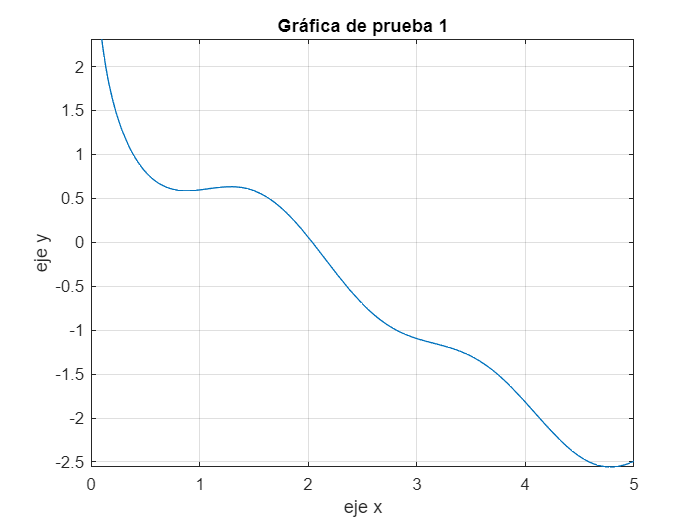

fplot(y)
grid on, xlabel('eje x'), ylabel('eje y'),title('Gráfica de prueba 1')

Se inicia el toolbox de varibles simbólicas

syms x y

Vamos a resolver la siguente ecuación cuadratica de segundo orden

d = x.^2 - 5*x - 5;
a=solve(d)

$$a = \left(\begin{array}{c} \frac{5}{2}-\frac{3\,\sqrt{5}}{2}\\ \frac{3\,\sqrt{5}}{2}+\frac{5}{2} \end{array}\right)$$

Si requerimos ayuda para un comando, la llamamos como 

Ahora la pedimos

help dsolve

 dsolve Symbolic solution of ordinary differential equations.
    dsolve will not accept equations as strings in a future release.
    Use symbolic expressions or sym objects instead.
    For example, use syms y(t); dsolve(diff(y)==y) instead of  dsolve('Dy=y').
 
    dsolve(eqn1,eqn2, ...) accepts symbolic equations representing
    ordinary differential equations and initial conditions. 
 
    By default, the independent variable is 't'. The independent variable
    may be changed from 't' to some other symbolic variable by including
    that variable as the last input argument.
 
    The DIFF function constructs derivatives of symbolic functions (see sym/symfun).
    Initial conditions involving derivatives must use an intermediate
    variable. For example,
      syms x(t)
      Dx = diff(x);
      dsolve(diff(Dx) == -x, Dx(0) == 1)
 
    If the number of initial conditions given is less than the
    number of dependent variables, 

Tambien se puede usar el comando dsolve para resolver ecuaciones diferenciales de la siguente manera

syms x(t) a
dsolve(diff(x) == -a*x)

$$ans = C_{1}\,{\mathrm{e}}^{-a\,t}$$